## 1. feladat

[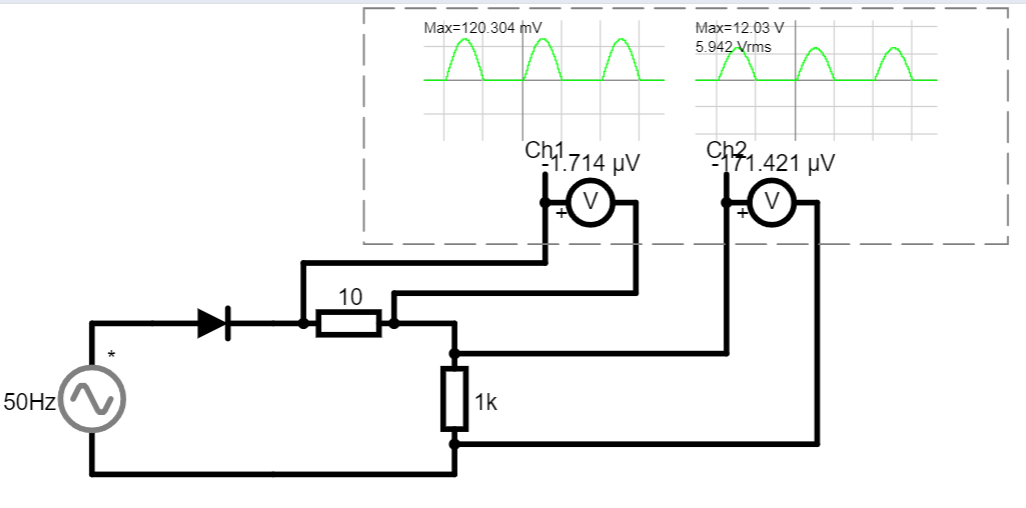](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgA3EYibNbiMlL8ayKqLTQs2UlDkwEbAO4CQfFMRrrIbACYhSxFMI2iT-XQwBmAQwCuAGwAuytWkHmERoSNdovxvz+RhgEUH4B6sFqAToq0erImmrS4QBOMSGEmTmi8K48gQbeJnGmRchYJb4YlPiCaGH1xeAgAMIAFuy14HAojb00hq2daGwZldVuHiIoZZMVVeXzS0k0zWvhKhvJGwNlaO5Fh4JLB0cLuAj8C2VXN0v3-WEHkdlgfaFbg2rvfcj7CIhAJgMBhaJlUHgkFg57hAAOID2TWucPoNB0iI+EjCULR8jYH3o7nW-FwxDCwy0uAA+jwaZAaR9SAQGdBkF5-GzkDSWDT2ESkQQILh+AgAS0tGA6dLGRgwWgaRhubyeewAEa-aFUMCyDkYthAA)

## 2. feladat

[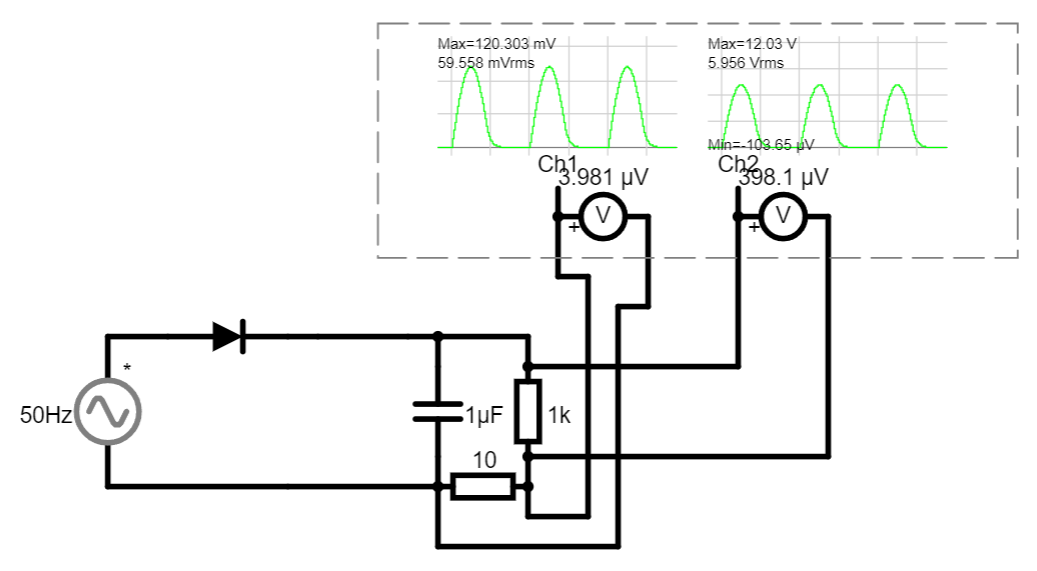](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgA3EYibNbiMlL8ayKqLTQs2UlDkwEbAO4CQfFMRrrIbACYhSxFMI2iT-XQwBmAQwCuAGwAuytWDP80BAsZGuvPkKe3mqEUP4h6gFqCEY6KmjuatKmyX4ATmqRYdFosXKocK48vgZGQeEqyJqlyFjlJjoYlPiCXiCtZeAgAMIAFuzN4HAo7e40ht39aGyZiVopuSmi8Sj1pWiJpaud1TS77TsI-HVGuMejPqu5YeOhV653GD53yIcRPnlGYGCf+as-P7fX6XcIABw6kDaPnOJ3a9BoOghrzGILeMPkbHc9HmHX4uGIPkmWkgAH0eKSyRhfmhKdBkLE8nTkKSWKT2NiOgQILh+Ag3l0tCyKVTIHgCKSMMzWSz2AAje4xKhgWQMxH+JIVXHPSpuBaeJJfcIAYz1iu1-ygsHgkDECFguFI3II+AIpDAx2J1vYCU15i2FWukUWkRCQc+IV5WjDrijWRhGFSO0Te0hghqRxO61wBLWcVjudOHVznR2JahZtLGv2Fe1yzYQA)

[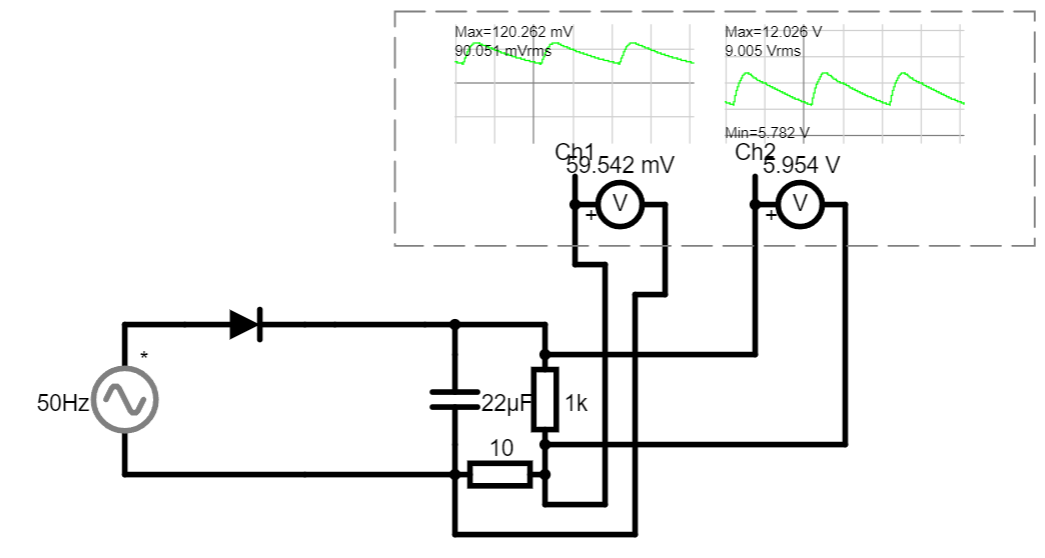](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgA3EYibNbiMlL8ayKqLTQs2UlDkwEbAO4CQfFMRrrIbACYhSxFMI2iT-XQwBmAQwCuAGwAuytWDP80BAsZGuvPkKe3mqEUP4h6gFqCEY6KmjuatKmyX4ATmqRYdFosXKocK48vgZGQeEqyJqlyFjlJjoYlPiCXiCtZeAgAMIAFuzN4HAo7e40ht39aGyZiVopuSmi8Sj1pWiJpaud1TS77TsI-HVGuMejPqu5YeOhV653GD53yIcRPnlGYGCf+as-P7fX6XcIABw6kDaPnOJ3a9BoOghrzGILeMPkbHc9HmHX4uGIPkmWkgAH0eKSyRhfmhKdBkLE8nTkKSWKT2NiOgQILh+Ag3l0tCyKVTIHgCKSMMzWSz2AAje4xKhgWQMxH+JIVXHPSpuBaeJJfcIAYz1iu1-ygsHgmxAWCk0jAPEMaGQuGkJRgcHYCU15i2FWukUWkRCQc+IV5WjDrijWRhGFSO0Te0hghqRxO61wBLWcVjudOHVznR2JahZtLGv2Fe1yzYQA)


$$\Delta \;U=U_b =\frac{I_f \cdot T_{\mathrm{kis}} }{C_p }\approx \;\frac{I_f \cdot T}{C_p }$$


Ebből látható, hogy az $R_t$ellenállás értéke fordítottan arányos a bugófeszültséggel.

U_b_calc = @(I_f, T, C_p) (I_f .* T) ./  C_p;

freq = 50;
U_f = 9;
R_t = 1000;
T = 1 / freq;
C_p = 22 * 10^-6;
I_f = U_f / R_t

I_f = 0.0090


U_b = U_b_calc(I_f, T, C_p)

U_b = 8.1818

$I_f =9\mathrm{mA}$ átlagos feszültségen $U_b =8\ldotp 18\;V$ effektív búgási feszültség a számolt érték. Kerekítési hibákra számítunk, mert $T\not= T_{\mathrm{kisülés}}$ 

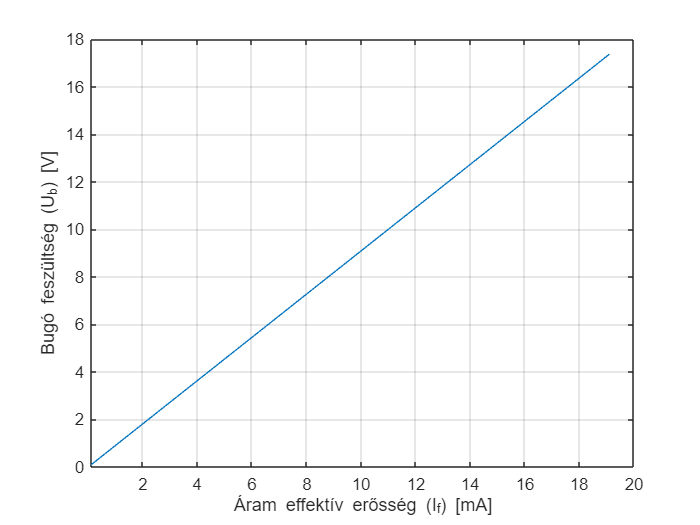

I_f_start = 0.1;
I_f_end = 20;
I_f = (I_f_start:I_f_end) .* 10^-3;


plot(I_f .* 1000, U_b_calc(I_f, T, C_p)); grid on;
xlabel("Áram effektív erősség (I_f) [mA]");
ylabel("Bugó feszültség (U_b) [V]");  
xlim([I_f_start, I_f_end]);

## 3. feladat

[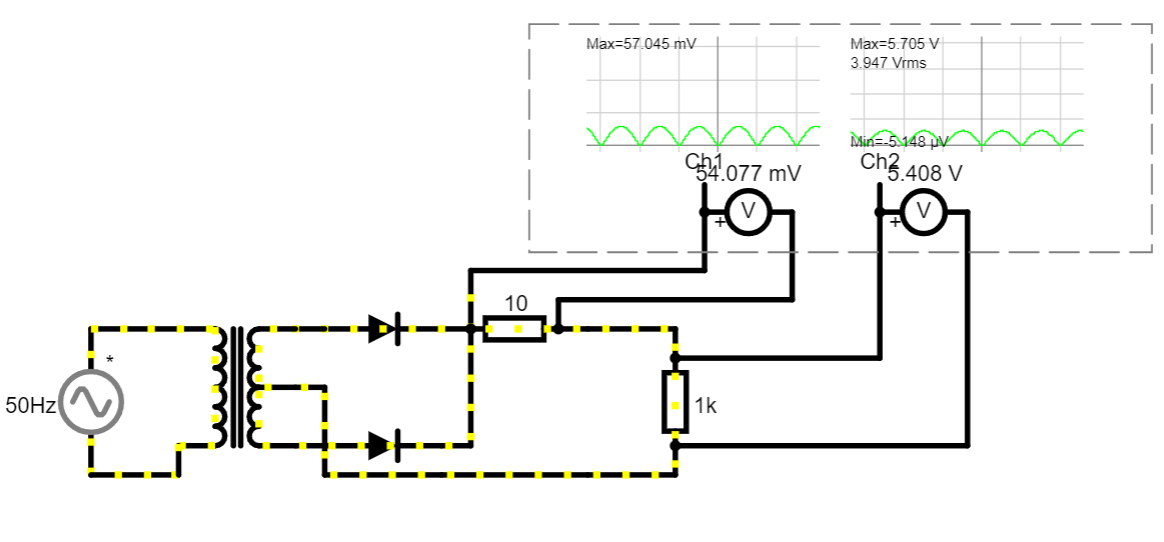](https://falstad.com/circuit/circuitjs.html?ctz=CQAgrCAMB0l3ECMMBMcUHYMGZIA4UA2ATmI3EnBABZtwBTAWkUQCgA3ER7FETX7r0TFelRBRCIU0DJmJQFMMKwAmIYoUkjJhMdt4r6AMwCGAVwA2AF1YB3PtT28UePFtF2+r917do3kJ4ufrK+fGCagfYojnyhiLpxHgBOYf5pEQrIcJ54Tuqawh72CfmIGIXagWjkuNSSLiB1BTQgAMIAFmw1NHANbo6UGq2dKKyp5ZXOMT5iUZIVPpM6lPPLpU2Q9RvzzRt7jfMoM0V8J4tH55rYYEIXnjd317f9UEHe6YN8+G-2X599KQBd5+TLUaigyKecGQmgQ16BAAOm22jUerzoq1YyK+QLhbjxmLejjoMUoPCahDcw0oxwA+oRqHTIHTHMQ8MzoNgpGBOYg6cw6WwSU08PUKWApC1adgGUyWTVsBzHHyBfy2AAjb6g8DUeSIMBY6KxU7HbZVIKxfhpUJrRYoTLrC32YbWjbWtaJB2Fe2ZT0+QSzTyBt2aD2qFrelbhMMgQymSw2BL6qYgPKzVriRgwSAG4hSQjYbAidl4XBKyQyRDUSXYQhAwhgdkYJjkHNbPCMw2l4T1xwQGCkTwJJI6GO-NO0zKuv2eV2hV0zeaL+rps1vIA)

## 4. feladat

[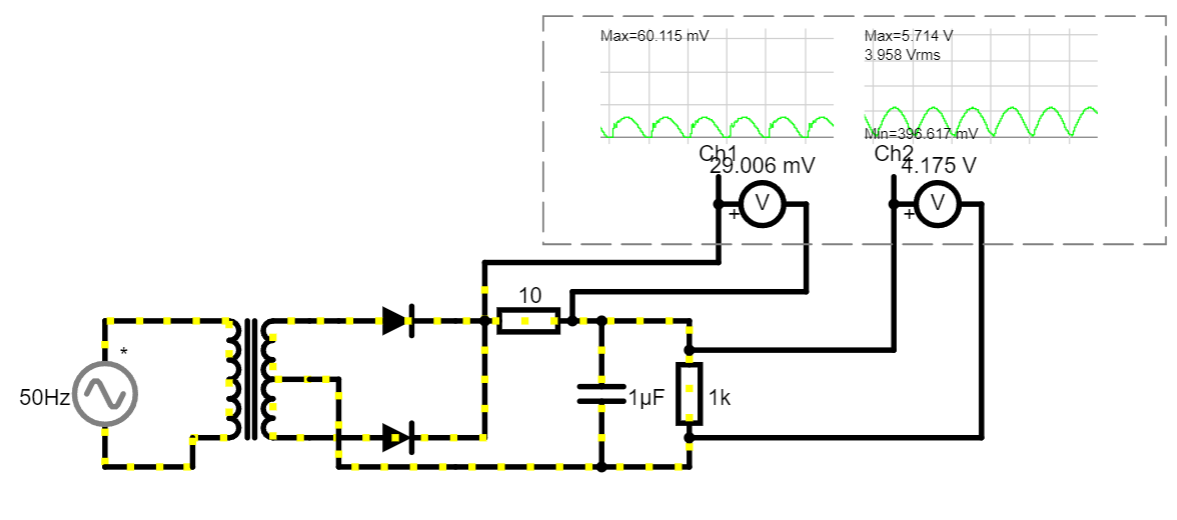](https://falstad.com/circuit/circuitjs.html?ctz=CQAgrCAMB0l3ECMMBMcUHYMGZIA4UA2ATmI3EnBABZtwBTAWkUQCgA3ER7FETX7r0TFelRBRCIU0DJmJQFMMKwAmIYoUkjJhMdt4r6AMwCGAVwA2AF1YB3PtT28UePFtF2+r917do3kJ4ufrK+fGCagfYojnyhiLpxHgBOYf5pEQrIcJ54Tuqawh72CfmIGIXagWjkuNSSLiB1BTQgAMIAFmw1NHANbo6UGq2dKKyp5ZXOMT5iUZIVPpM6lPPLpU2Q9RvzzRt7jfMoM0V8J4tH55rYYEIXnjd317f9UEHe6YN8+G-2X599KQBd5+TLUaigyKecGQmgQ16BAAOm22jUerzoq1YyK+QLhbjxmLejjoMUoPCahDcw0oxwA+oRqHTIHTHMQ8MzoNgpGBOYg6cw6WwSU08PUKWApC1adgGUyWTVsBy0HyBfy2AAjb6g8DUeSIMBY6KxU7HbZVIKxfhpUJrRYoTLrC32YbWjbWtaJB2Fe2ZT0+QSzTyBt2aD2qFrelbhMMgQymSw2BL6qYgPKzVriGCQBLYDCGvLUKRbYhbLjZrZ6zB4MDYUgaTCETTMGSIajHKQkEg8SBgahMcgwUieBJJHQx35p2mZV1+zyu0KumbzJf1dNmt4AYwc+TJY9WsHgOfA0BQeZQxGw1AiYAqUorbCAA)

[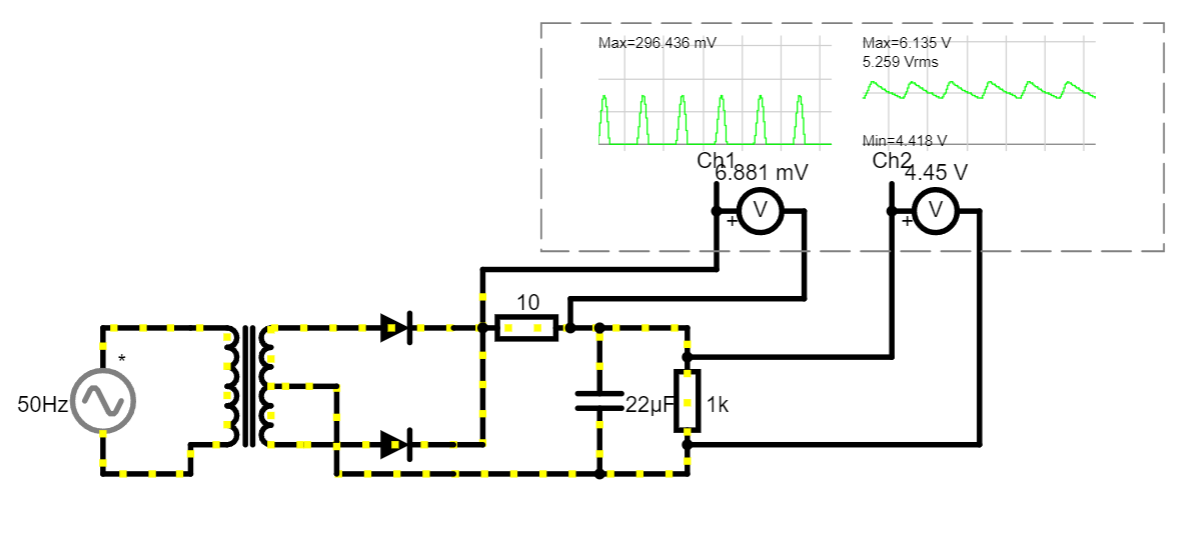](https://falstad.com/circuit/circuitjs.html?ctz=CQAgrCAMB0l3ECMMBMcUHYMGZIA4UA2ATmI3EnBABZtwBTAWkUQCgA3ER7FETX7r0TFelRBRCIU0DJmJQFMMKwAmIYoUkjJhMdt4r6AMwCGAVwA2AF1YB3PtT28UePFtF2+r917do3kJ4ufrK+fGCagfYojnyhiLpxHgBOYf5pEQrIcJ54Tuqawh72CfmIGIXagWjkuNSSLiB1BTQgAMIAFmw1NHANbo6UGq2dKKyp5ZXOMT5iUZIVPpM6lPPLpU2Q9RvzzRt7jfMoM0V8J4tH55rYYEIXnjd317f9UEHe6YN8+G-2X599KQBd5+TLUaigyKecGQmgQ16BAAOm22jUerzoq1YyK+QLhbjxmLejjoMUoPCahDcw0oxwA+oRqHTIHTHMQ8MzoIQUGBOYg6cw6WwSU08PUKWApC1adgGUyWTVsBzkHyBfy2AAjb6g8DUeSIMBY6KxU7HbZVIKxfhpUJrRY8wqLU7zYbWjbWtaJB0LTTez0+QSzTyBt2+22qFre92ZAzGczWVgJfVTEB5WatcQwOB1MCkXPYHCQA2QCDcWBobC4SCVoiIXBYJjkZgyRC0Ij4EjIbDEagoRtQaCkTwJJI6cJQ+xp72uzIusO8V0zOdnepTpesADGDnyZNHq1g8GONGgtx7xDA2GoBsIBpuA7gbCAA)


$$\Delta \;U=U_b =\frac{I_f }{C_p }\cdot \frac{T_{\textrm{kis}} }{2}\approx \;\frac{I_f }{C_p }\cdot \frac{T}{2}$$



$$I_f =\frac{U_f }{R_t }$$



$$U_b \approx \frac{U_f }{R_t \cdot C_P }\cdot \frac{T}{2}$$


Ebből látható, hogy az $R_t$ellenállás értéke fordítottan arányos a bugófeszültséggel.

U_b_calc = @(I_f, T, C_p) (I_f .* (T / 2)) ./  C_p;

freq = 50;
U_f = 9;
R_t = 1000;
T = 1 / freq;
C_p = 22 * 10^-6;
I_f = U_f / R_t

I_f = 0.0090


U_b = U_b_calc(I_f, T, C_p)

U_b = 4.0909

$I_f =9\mathrm{mA}$ átlagos feszültséges $U_b =4\ldotp 09\;V$ effektív búgási feszültség a számolt érték.

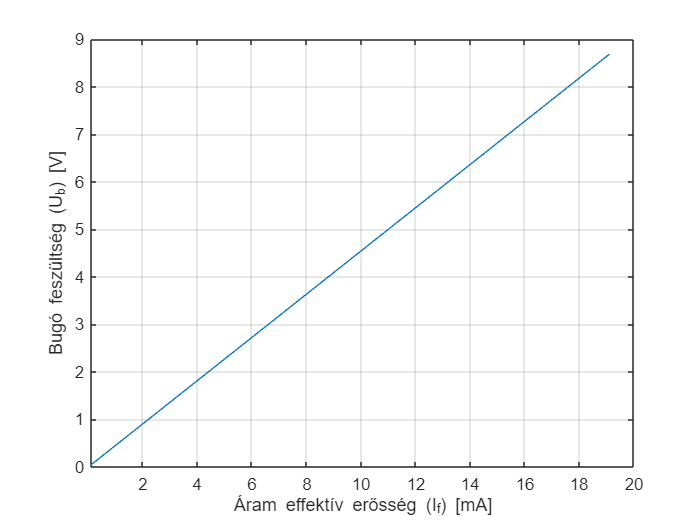

I_f_start = 0.1;
I_f_end = 20;
I_f = (I_f_start:I_f_end) .* 10^-3;


plot(I_f .* 1000, U_b_calc(I_f, T, C_p)); grid on;
xlabel("Áram effektív erősség (I_f) [mA]");
ylabel("Bugó feszültség (U_b) [V]"); 
xlim([I_f_start, I_f_end]);